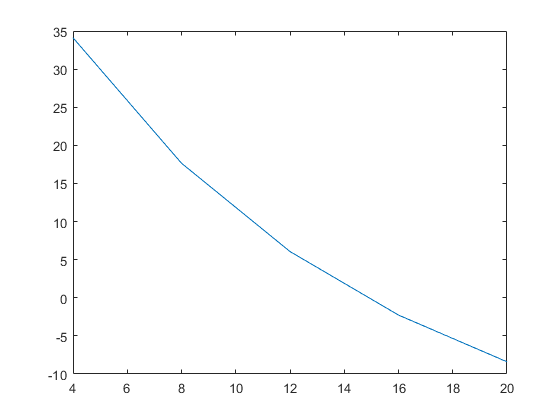


c = [4 8 12 16 20];
g = 9.8;
m = 68.1;
t = 10;
v = 40;

fc = (((g*m)./c).*(1 - exp(-(c/m)*t)) - v);
plot(c,fc);

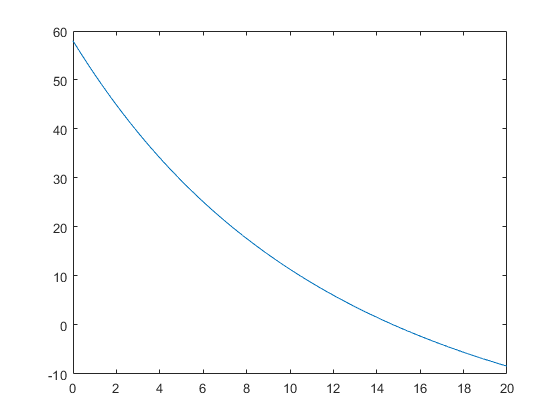

c = [0:0.0001:20];
fc = (((g*m)./c).*(1 - exp(-(c/m)*t)) - v);
plot(c,fc);

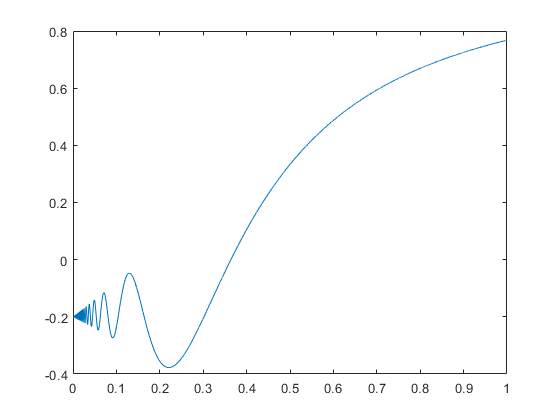


x = [0:0.0001:1];
fx = x .* sin(1./x) - (0.2 * exp(-x));
plot(x,fx);

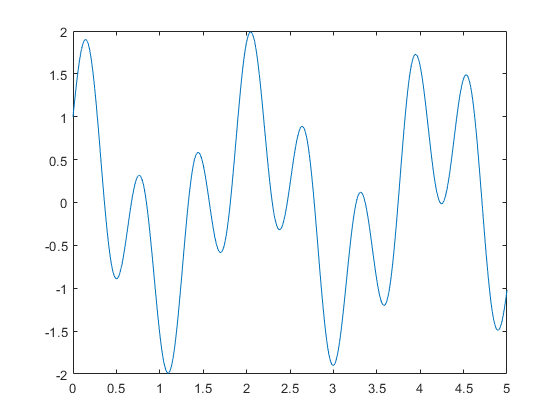

x = [0:0.0001:5];
fx = sin(10.*x) + cos(3.*x);
plot(x,fx);

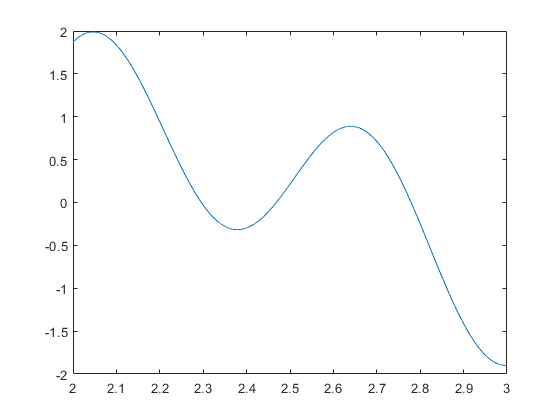

x = [2:0.0001:3];
fx = sin(10.*x) + cos(3.*x);
plot(x,fx);

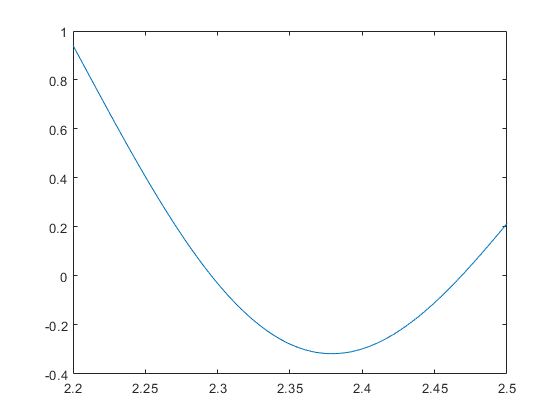

x = [2.2:0.0001:2.5];
fx = sin(10.*x) + cos(3.*x);
plot(x,fx);

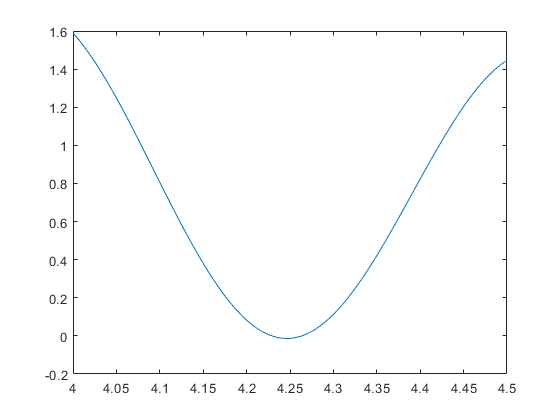

x = [4:0.0001:4.5];
fx = sin(10.*x) + cos(3.*x);
plot(x,fx);

# Bisección

limi=12;
lims=16;
es=0.5;

syms c;
f=(((g*m)./c).*(1 - exp(-(c/m)*t)) - v);
 
f1=subs(f,c,limi);
f2=subs(f,c,lims);
i=1;
ea(i)=100;
if (f1*f2) < 0
    iter(i) = i;
    xi(i)=limi;
    xs(i)=lims;
    f1=subs(f,c,xi(i));
    f2=subs(f,c,xs(i));
    
    xr(i)=(xi(i)+xs(i))/2; 
    f3=subs(f,c,xr(i));
    et(i)=abs((14.7802-xr(i))/14.7802*100);
    while abs(ea(i)) >= es
      if f1*f3<0
         xi(i+1)=xi(i);
         xs(i+1)=xr(i);
         f1=subs(f,c,xi(i+1));
         f2=subs(f,c,xs(i+1));
      end
      if f1*f3> 0
         xi(i+1)=xr(i);
         xs(i+1)=xs(i);
         f1=subs(f,c,xi(i+1));
         f2=subs(f,c,xs(i+1));
      end      
      xr(i+1)=(xi(i+1)+xs(i+1))/2; 
      f3=subs(f,c,xr(i+1));
      
      ea(i+1)=abs((xr(i+1)-xr(i))/(xr(i+1))*100);
      et(i+1)=abs((14.7802-xr(i+1))/14.7802*100);
      iter(i+1) = i+1;
      i=i+1;
    end
    table(iter',xi',xs',xr',ea',et','VariableNames',{'I','XI','Xu','Xr','Ea','Et'})
else
   fprintf('No hay raices');
end

ans = 6×6 table
    I     XI        Xu        Xr        Ea         Et   
    _    _____    ______    ______    _______    _______

    1       12        16        14        100     5.2787
    2       14        16        15     6.6667     1.4871
    3       14        15      14.5     3.4483     1.8958
    4     14.5        15     14.75     1.6949    0.20433
    5    14.75        15    14.875    0.84034     0.6414
    6    14.75    14.875    14.813    0.42194    0.21854
